% linear equalizer based on RLS

clc
clear all
close all
training_len = 10^4; % length of the training sequence
snr_dB = 20;         % SNR in dB
equalizer_len = 8;   % length of the equalizer
f_fac = 0.999;       % forgetting factor
delta = 100;         % value to initialize P(0)

% SNR parameters
snr = 10^(0.1*snr_dB);
noise_var = 1/(2*snr);  % noise variance

% source
training_a = randi([0 1],1,training_len)

training_a =      1     1     0     1     1     0     0     1     1     1     0     1     1     0     1     0     0     1     1     1     1     0     1     1     1     1     1     0     1     0     1     0     0     0     0     1     1     0     1     0     0     0     1     1     0     0     0     1     1     1


% bpsk mapper (bit '0' maps to -1 and bit '1' maps to +1)
training_seq =2*training_a-1

training_seq =      1     1    -1     1     1    -1    -1     1     1     1    -1     1     1    -1     1    -1    -1     1     1     1     1    -1     1     1     1     1     1    -1     1    -1     1    -1    -1    -1    -1     1     1    -1     1    -1    -1    -1     1     1    -1    -1    -1     1     1     1


%channel
H = [0.26 0.93 0.26];      % impulse response
H = H/norm(H);
chan_len  = length(H);
% noise
noise = normrnd(0,sqrt(noise_var),1,training_len+chan_len-1);
% channel output
chan_op = conv(H,training_seq)+noise;
% RLS algorithm
equalizer = zeros(equalizer_len,1);
P_matrix = delta*eye(equalizer_len,equalizer_len);
for i = 1:training_len-equalizer_len+1
    equalizer_ip = transpose(fliplr(chan_op(i:i+equalizer_len-1)));
    alpha = training_seq(i+equalizer_len-1)-equalizer_ip.'*equalizer;
    g = P_matrix*equalizer_ip/(f_fac+equalizer_ip.'*P_matrix*equalizer_ip);
    P_matrix = (1/f_fac)*P_matrix-g*equalizer_ip.'*(1/f_fac)*P_matrix;
    equalizer = equalizer+alpha*g;
end
equalizer = equalizer.' 

equalizer =     0.3629   -0.1810    0.0869   -0.0628    0.0276   -0.0043    0.0198   -0.0173


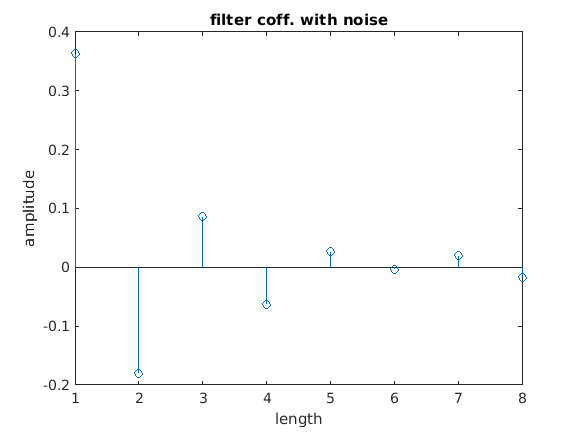

stem(equalizer);title('filter coff. with noise');xlabel('length');ylabel('amplitude');



chan_opt_withoutnoise=conv(H,training_seq);
% RLS algorithm
equalizer = zeros(equalizer_len,1);
P_matrix = delta*eye(equalizer_len,equalizer_len);
for i = 1:training_len-equalizer_len+1
    equalizer_ip = transpose(fliplr(chan_opt_withoutnoise(i:i+equalizer_len-1)));
    alpha = training_seq(i+equalizer_len-1)-equalizer_ip.'*equalizer;
    g = P_matrix*equalizer_ip/(f_fac+equalizer_ip.'*P_matrix*equalizer_ip);
    P_matrix = (1/f_fac)*P_matrix-g*equalizer_ip.'*(1/f_fac)*P_matrix;
    equalizer1 = equalizer+alpha*g;
end
figure
equalizer1 = equalizer1.' 

equalizer1 =     0.0017   -0.0013   -0.0013    0.0021   -0.0022    0.0020   -0.0013   -0.0009


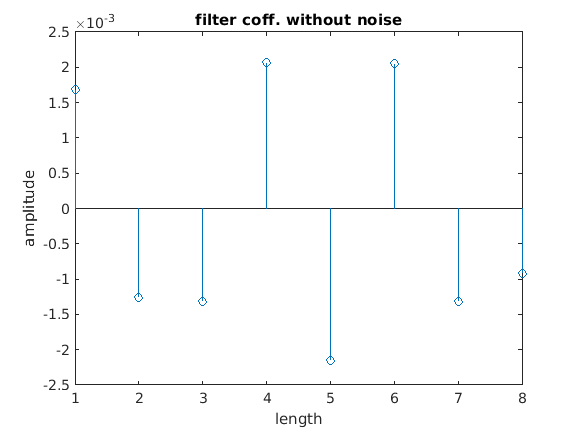

stem(equalizer1);title('filter coff. without noise');xlabel('length');ylabel('amplitude');